# **Extended Kalman Filter Implementation**

This lesson is for extended integrate prediction and update step.

clear 
simulDuration = 300;
R = 0.1; 
L = 0.05; 

viz = Visualizer2D;
viz.mapName = 'map';
viz.robotRadius = L; 
mobileRobot = DifferentialDrive(R,L);

detector = ObjectDetector;
detector.fieldOfView = pi/2; % Field of View [rad]
detector.maxRange = 1; % Max range distance [m]        
detector.maxDetections = 5; % Max number of detections
attachObjectDetector(viz,detector);
                
[map, mapDilatation]  = generateAugmentedMap(which('world1.png'), 0.1, 10, L); %[path, treshold, scale,robotRadio]

Select start and stop position by click ( last point is the goal).

[initPose,goalPose] = initGoalPosebyClick(mapDilatation); close

Choose init and goal angle.

initPose(3) = 1.59;
goalPose(3) = 1.55;

Choose (by click) landmarks coordinates.

[objects,colors,markers] = objectsByClick(map); close
viz.objectColors = colors;
viz.objectMarkers = markers;

[pthObj, solnInfo] = getPathRRT(mapDilatation,initPose,goalPose,0.1,.1,.2,90000); %[map,initPose,goalPose,MinTurningRadius,ValidationDistance,MaxConnectionDistance,MaxIterations]
              
[controller] = controllerPP(pthObj,0.1,0.1,pi/4); %[pthObj,LookaheadDistance,DesiredLinearVelocity,MaxAngularVelocity)]

Define Covariance matrices.

Q = [0.001  0.00  0.00;  % Each variable is only related itself.
     0.00  0.001  0.00; 
     0.00  0.00  0.001];
RR = [0.03 0 0;
      0 0.002 0;
      0 0 1e-11];
alpha= [ 0.9 0.3 0.601 0.001 ];

Defind noise parameters.

varianceV= 0.01; %.3 
varianceW= 0.017; % .1
varianceR = 0.5;
varianceT = 0.05;

sigma = [0 0 0;  %Covariance matrix start with all elements zero
         0 0 0; 
         0 0 0];

currentPose = initPose;

[sampleTime,tVec,r] = simulTime(.3,simulDuration);
odom_pose = zeros(3,numel(tVec));
odom_pose(:,1) = initPose;

svArray = zeros(3,numel(tVec));
svArray(:,1) = initPose;


Run simulation


for idx = 2:numel(tVec) 
      
    if( sqrt( (svArray(1,idx-1)-pthObj.States(end,1))^2 + (svArray(2,idx-1)-pthObj.States(end,2))^2 )  < L/2  )
       break
    end
    

    [v,w,lookAheadPt] = controller(svArray(:,idx-1));
    
    [wL,wR] = inverseKinematics(mobileRobot,v ,w);
        
    % Store each pose computed by odometry
    odom_pose(:,idx) =  computeOdometry(R,L,wR,wL,sampleTime ,odom_pose(:,idx-1));

%Add noise to velocities
    v = v  + abs(normrnd(0,varianceV));
    w = w + normrnd(0,varianceW);
    bodyV = [v ;0;w];    % Body velocities [vx;vy;w]  vy = 0 because the differential robot can not move in y axis.
        
    % Convert from robot body to world
    vel =  bodyToWorld(bodyV,currentPose);  
       
    % Perform forward discrete integration step
    currentPose = currentPose + vel * sampleTime; 
   
    % Update visualization
    viz(currentPose,objects);
    hold on
    if idx ==2
       interpolate(pthObj,300)
       plot(pthObj.States(:,1), pthObj.States(:,2), 'r-', 'LineWidth', 2) % Red Path compute by RTT*
    end

    

### **Prediction Step**


    [sv, u] = sampleOdometry(odom_pose(:,idx-1),odom_pose(:,idx),svArray(:,idx-1),alpha);
             
    G = [ 1 0  -u(2)*sin(u(1));
          0 1   u(2)*cos(u(1));
          0 0         1       ];
          
    sigma =  G*sigma*G.' + Q;

    detections = detector(currentPose,objects);
   

### Actualization step for each landmark detected at the moment

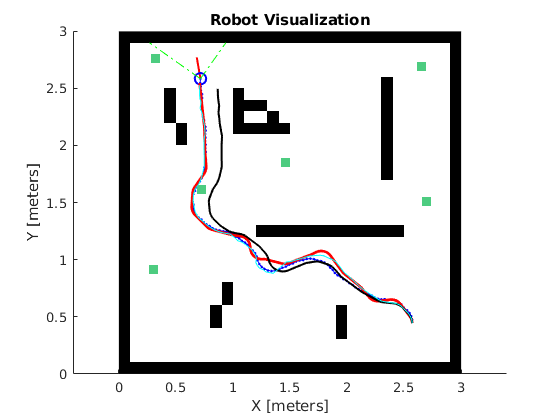


    for i = 1:size(detections,1)
        
        %Real measurement
         z = [ detections(i,1);
               detections(i,2) ;
               0                 ];
          
        %Get landmark id
        for j = 1:size(objects,1)
            if objects(j,3) == detections(i,3)
                id_landmark = j;
            end
        end
        
        
        dist = power(objects(id_landmark,1) - sv(1), 2) + power(objects(id_landmark,2) - sv(2), 2); 
        
        %Computing expected sensor readings
        z_hat = [ sqrt(dist);
                  normalizeAngle(  atan2(objects(id_landmark,2) - sv(2), objects(id_landmark,1) - sv(1) ) - sv(3) ) ;
                  0];
              
        % Jacobian of function h(sv,S)
        H = [ -( objects(id_landmark,1) - sv(1) ) / sqrt(dist),  -( objects(id_landmark,2) - sv(2) ) / sqrt(dist), 0;
            ( objects(id_landmark,2) - sv(2)) / dist, -( objects(id_landmark,1) - sv(1) ) / dist,-1;
			 	  0,0,0];
        
        
       %Computing Kalman gain
       K =  (sigma* (H.')) /((H*sigma*(H.')) + RR);
      
       
       %Update state vector (sv) and covariance matrix (sigma)
       sv = sv +  (K*(z-z_hat));
       sigma = (eye(3) - (K*H)  ) * sigma;
       
       sv(3) = normalizeAngle(sv(3));
        
    end
    svArray(:,idx) = sv;
    
    %Show error elipses
    h2 = error_ellipse(sigma(1:2,1:2), svArray(1:2,idx) );
    %Wait for visualization rate
    waitfor(r);
    set(h2,'Visible','off')

   
end


hold on
plot(odom_pose(1,1:idx-1),odom_pose(2,1:idx-1),'k-','LineWidth', 1.5); %Black Odometry reported by robot sensors
plot(svArray(1,1:idx-1),svArray(2,1:idx-1),'c'); % Cyan is trajectory reported by Prediction step of Kalman Filter   
hold off

As you can seen in simulation Ellipse error decrease when the robot execute actualization step. and the robot follows well the calculated path.

# Practice

Change "world1" map for "office", increase error parameters and configure Q RR alphas and RTT* parameters to execute a good trajectory.